clc
tic

t   = out.tout;
Uabc = out.ScopeData.signals(1).values;
Iabc = out.ScopeData.signals(2).values;
ud   = out.ScopeData1.signals(1).values;
id   = out.ScopeData1.signals(2).values;

tmin = t(1);
tmax = t(end);

%% ===================== 2) 风格1：全局绘图风格 =====================
set(groot, 'defaultFigureColor', 'w');

set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultAxesLineWidth', 1.1);
set(groot, 'defaultLineLineWidth', 1.6);
set(groot, 'defaultAxesBox', 'on');
set(groot, 'defaultAxesTickDir', 'out');

set(groot, 'defaultAxesTickLabelInterpreter', 'tex');
set(groot, 'defaultTextInterpreter', 'tex');
set(groot, 'defaultLegendInterpreter', 'tex');

% Colors
C1 = [0.00, 0.45, 0.74];   % blue
C2 = [0.85, 0.33, 0.10];   % orange
C3 = [0.47, 0.67, 0.19];   % green
C4 = [0.49, 0.18, 0.56];   % purple

%% ===================== 3) 交流侧 Iabc：重采样 + THD(50Hz) 频谱/指标 =====================
fs_line = 50;                      % 电网频率(Hz) —— THD 基波
Hlimit  = 50;                      % 计算到第 50 次谐波（可按题目/标准调整）

% -------- 3.1 检查是否等间隔采样，并重采样为均匀时间轴 --------
t = t(:);
Iabc = Iabc;                       % [N x 3]
dt = diff(t);
Fs_est = 1/mean(dt);

rel_jitter = (max(dt) - min(dt)) / max(mean(dt), eps);

if rel_jitter > 1e-3
    Fs  = Fs_est;
    t_u = (t(1):1/Fs:t(end)).';
    Iabc_u = interp1(t, Iabc, t_u, 'linear', 'extrap');
else
    Fs  = Fs_est;
    t_u = t;
    Iabc_u = Iabc;
end

% -------- 同步重采样 id（用于稳态放大显示，与频谱分析一致）--------
id = id(:);   % 保证列向量
if rel_jitter > 1e-3
    id_u = interp1(t, id, t_u, 'linear', 'extrap');
else
    id_u = id;
end


% -------- 3.2 取稳态段：末尾整周期截取 --------
Ncycle = 10;                       % 建议比你原来的 4 更大一点，谐波更稳（可调）
Tseg   = Ncycle / fs_line;

% 用"样本数"截取更稳：保证长度对应整周期时间
Ns = round(Tseg * Fs);
Ns = Ns - mod(Ns,2);               % 偶数长度
if Ns > length(t_u)
    Ns = length(t_u) - mod(length(t_u),2);
end

idx_end = length(t_u);
idx_sta = idx_end - Ns + 1;

Iseg = Iabc_u(idx_sta:idx_end, :); % [Ns x 3]

% -------- 稳态段内：最后五个周期（用于 id 放大图）--------
Ncycle_zoom = 5;                         % 放大展示的周期数
Tzoom       = Ncycle_zoom / fs_line;     % 5 个周期的时长
Ns5 = round(Tzoom * Fs);
Ns5 = Ns5 - mod(Ns5,2);                  % 取偶数，保持与你的习惯一致

% "最后五个周期"以整个仿真末尾为准（也就是与你 FFT 用的 idx_end 一致）
idx_zoom_sta = idx_end - Ns5 + 1;

% 防越界保护（极端情况下仿真时间太短）
idx_zoom_sta = max(idx_zoom_sta, 1);

t_id_zoom  = t_u(idx_zoom_sta:idx_end);
id_zoom    = id_u(idx_zoom_sta:idx_end);


% -------- 3.3 对每相做 FFT 并计算 THD --------
L  = size(Iseg,1);
w  = hann(L);
cg = mean(w);                      % coherent gain（与你原脚本一致）

f  = Fs*(0:(L/2))/L;

Hmax = min(Hlimit, floor((Fs/2)/fs_line));   % 不超过奈奎斯特
Ih_peak = zeros(Hmax, 3);          % 每次谐波 peak 幅值（窗修正后）
THD_phase = zeros(1,3);
I1_rms_phase = zeros(1,3);

for p = 1:3
    x = Iseg(:,p);
    x = x - mean(x);               % 去除 DC 偏置（THD 通常不含 DC）

    xw = x .* w;
    Y  = fft(xw);
    P2 = abs(Y)/L;

    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);   % 单边谱
    P1 = P1 / cg;                  % coherent gain 修正：得到 peak 幅值

    % 抽取整数倍 50Hz 的谐波幅值
    for k = 1:Hmax
        [~, idx] = min(abs(f - k*fs_line));
        Ih_peak(k,p) = P1(idx);
    end

    Ih_rms = Ih_peak(:,p) / sqrt(2);  % peak -> rms
    I1     = Ih_rms(1);
    THD_phase(p) = sqrt(sum(Ih_rms(2:end).^2)) / max(I1, eps) * 100;
    I1_rms_phase(p) = I1;
end

THD_max = max(THD_phase);

fprintf('====================================\n');

fprintf('variable-step重采样判定: rel_jitter = %.3g\n', rel_jitter);

variable-step重采样判定: rel_jitter = 1.9


fprintf('等效采样频率 Fs = %.3f Hz\n', Fs);

等效采样频率 Fs = 18996.000 Hz


fprintf('稳态截取: Ncycle = %d, 样本点 Ns = %d\n', Ncycle, Ns);

稳态截取: Ncycle = 10, 样本点 Ns = 3798


fprintf('基波(50Hz) RMS: Ia=%.6g A, Ib=%.6g A, Ic=%.6g A\n', I1_rms_phase(1), I1_rms_phase(2), I1_rms_phase(3));

基波(50Hz) RMS: Ia=71.4942 A, Ib=71.4671 A, Ic=71.4937 A


fprintf('THD(%%): Ia=%.4f %%, Ib=%.4f %%, Ic=%.4f %%\n', THD_phase(1), THD_phase(2), THD_phase(3));

THD(%): Ia=3.4811 %, Ib=3.4472 %, Ic=3.5040 %


fprintf('THD_max = %.4f %%  (要求 <= 7%%)\n', THD_max);

THD_max = 3.5040 %  (要求 <= 7%)


fprintf('====================================\n');

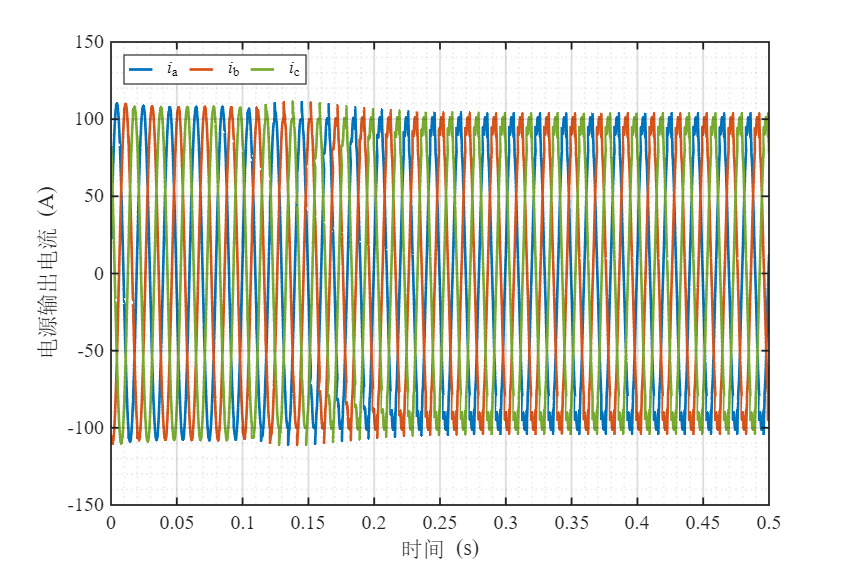


% -------- 3.4 频谱柱状图数据：按 50Hz 倍频画（用三相平均 or 最差相）--------
Kplot = min(Hmax, 50);                         % 画到第 50 次（可调）
ff   = (1:Kplot) * fs_line;                    % 50,100,...（不画 0Hz）
Abar = mean(Ih_peak(1:Kplot,:), 2);            % 三相平均的 peak 幅值
% 若你想画"最差相"的谐波谱，可改成：
% [~, pWorst] = max(THD_phase);
% Abar = Ih_peak(1:Kplot, pWorst);

%% ===================== 4) 风格1：分开绘制 4 个独立图 =====================

% ---- (1) Iabc ----
fig1 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax1 = axes(fig1); %#ok<LAXES>
plot(t, Iabc(:,1), 'Color', C1); hold on;
plot(t, Iabc(:,2), 'Color', C2);
plot(t, Iabc(:,3), 'Color', C3);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}电源输出电流\fontname{Times New Roman} (A)');

leg1 = legend({'{\it i}_a','{\it i}_b','{\it i}_c'}, ...
    'Location','northwest','NumColumns',3);
set(leg1, 'FontName','Times New Roman', 'FontSize', 11, ...
    'Box','on', 'EdgeColor',[0.2 0.2 0.2], 'LineWidth', 0.8, ...
    'Color','white', 'TextColor','black', 'ItemTokenSize',[14 10]);

ax1.GridAlpha = 0.15; ax1.MinorGridAlpha = 0.08;
set(ax1, 'Layer', 'top');

% ---- (2) ud ----
fig2 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax2 = axes(fig2); %#ok<LAXES>
plot(t, ud, 'Color', C1);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}总输出电压\fontname{Times New Roman} (V)');
ax2.GridAlpha = 0.15; ax2.MinorGridAlpha = 0.08;
set(ax2, 'Layer', 'top');

% ---- (3) id ----
fig3 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax3 = axes(fig3); %#ok<LAXES>
plot(t, id, 'Color', C4);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}总输出电流\fontname{Times New Roman} (A)');
ax3.GridAlpha = 0.15; ax3.MinorGridAlpha = 0.08;
set(ax3, 'Layer', 'top');

% ---- (4) 频谱柱状图：交流侧电流谐波谱(基波=50Hz) ----
fig4 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax4 = axes(fig4); %#ok<LAXES>
bar(ff, Abar, "LineWidth", 1.2, "FaceColor", C3);
grid on; grid minor;
xlim([min(ff), max(ff)]);
ylim([0, max(Abar)*1.10]);

xlabel('\fontname{SimSun}频率\fontname{Times New Roman} (Hz)');
ylabel('\fontname{SimSun}谐波幅值(peak)\fontname{Times New Roman} (A)');
title(sprintf('\\fontname{SimSun}交流侧电流谐波谱(基波=50Hz)  THD_{max}=%.3f%%\\fontname{Times New Roman}', THD_max));

ax4.GridAlpha = 0.15; ax4.MinorGridAlpha = 0.08;
set(ax4, 'Layer', 'top');


% ---- (5) id 稳态末尾五周期放大图 ----
fig5 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax5 = axes(fig5); %#ok<LAXES>
plot(t_id_zoom, id_zoom, 'Color', C4);
grid on; grid minor;
xlim([t_id_zoom(1), t_id_zoom(end)]);

xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}总输出电流\fontname{Times New Roman} (A)');
title(sprintf('\\fontname{SimSun}总输出电流\\it i_d \\rm\\fontname{SimSun}稳态末尾%d个周期放大\\fontname{Times New Roman}', Ncycle_zoom));

ax5.GridAlpha = 0.15; ax5.MinorGridAlpha = 0.08;
set(ax5, 'Layer', 'top');


%% ===================== 5) 导出（四张图分别导出） =====================
print(fig1, '滤波PI结果_Iabc_风格1',  '-dpng', '-r600');

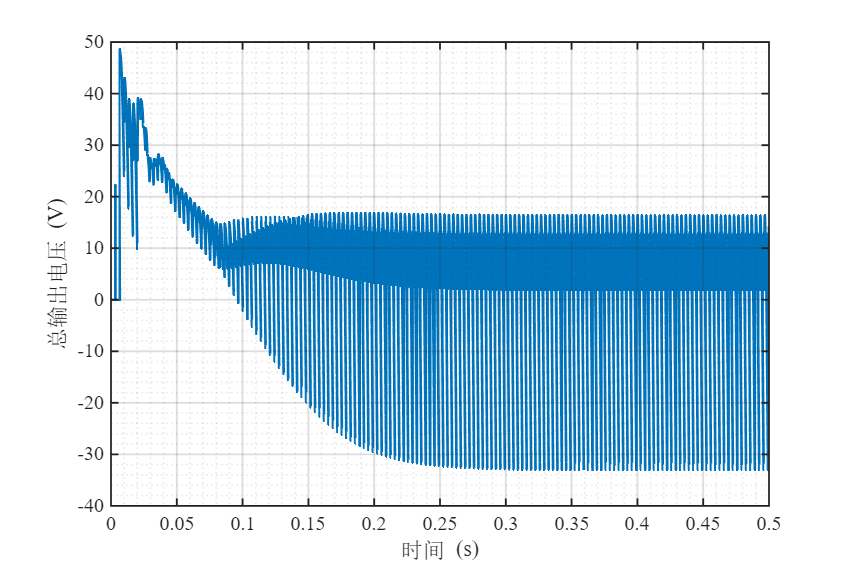

print(fig2, '滤波PI结果_ud_风格1',    '-dpng', '-r600');

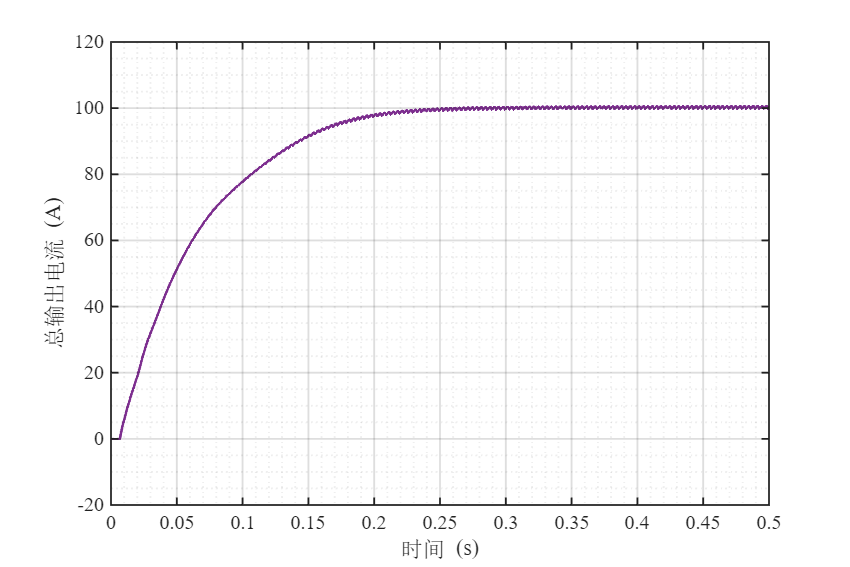

print(fig3, '滤波PI结果_id_风格1',    '-dpng', '-r600');

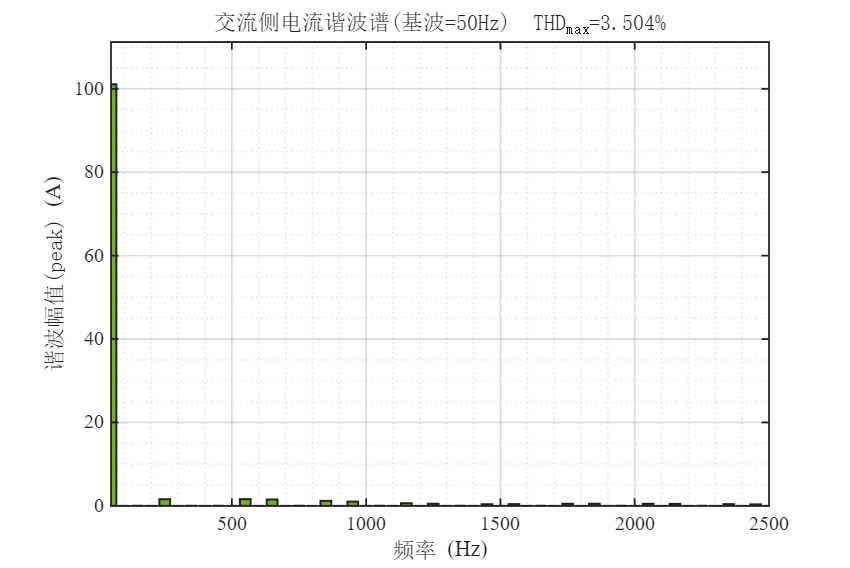

print(fig4, '滤波PI结果_Iabc_THD谐波谱_风格1',  '-dpng', '-r600');

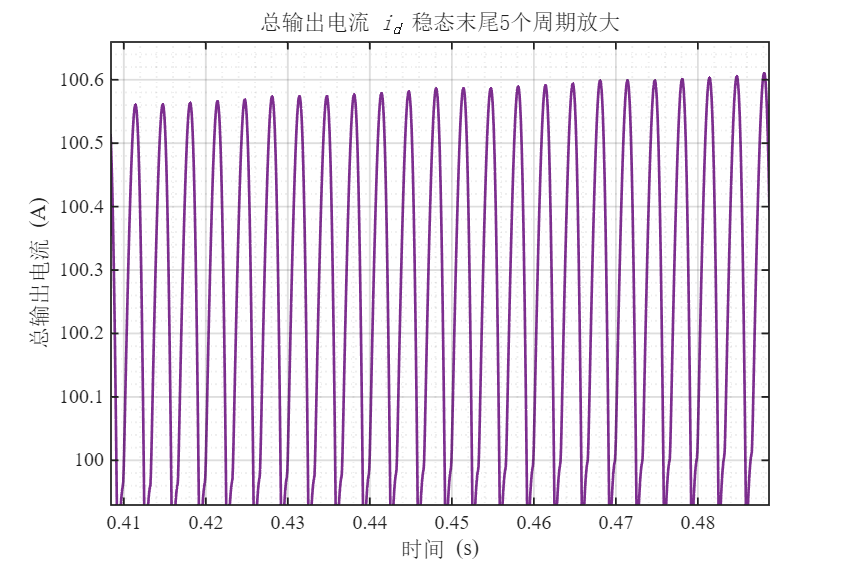

print(fig5, '滤波PI结果_id_稳态末尾五周期放大_风格1', '-dpng', '-r600');


toc

历时 14.418568 秒。
